# Technical Project

close all
clear, clc

## SCARA data

%m
d_0 = 1;        
a_1 = 0.5;
a_2 = 0.5;
l_1 = 0.25;
l_2 = 0.25;

%kg
m_l1 = 20;      
m_l2 = 20;
m_l3 = 10;
m_l = [m_l1 m_l2 m_l3];

%kg*m2
I_l1 = 4;       
I_l2 = 4;
I_l4 = 1;

%rad/m
k_r1 = 1;       
k_r2 = 1;
k_r3 = 50;
k_r4 = 20;

%kg*m2
I_m1 = 0.01;    
I_m2 = 0.01;
I_m3 = 0.005;
I_m4 = 0.001;

%N*m*s/rad
F_m1 = 0.00005; 
F_m2 = 0.00005;
F_m3 = 0.01;
F_m4 = 0.005;
F_m = [F_m1 F_m2 F_m3 F_m4];

syms theta_1 theta_2 d_3 theta_4 real
syms theta_dot_1 theta_dot_2 d_dot_3 theta_dot_4 real
syms theta_ddot_1 theta_ddot_2 d_ddot_3 theta_ddot_4 real

q = [theta_1, theta_2, d_3, theta_4]';
q_dot = [theta_dot_1 theta_dot_2 d_dot_3 theta_dot_4]';
q_dot_dot = [theta_ddot_1 theta_ddot_2 d_ddot_3 theta_ddot_4]'

$$q\_dot\_dot = \left(\begin{array}{c} {\ddot{\theta }}_{1}\\ {\ddot{\theta }}_{2}\\ {\ddot{d}}_{3}\\ {\ddot{\theta }}_{4} \end{array}\right)$$


dh = [a_1   0	    d_0 	    theta_1
      a_2   pi      0           theta_2
      0     0       d_3	        0
      0   	0       l_1+l_2		theta_4-pi/2];


## Calcolo Jacobiano

% Matrici trasformazione omogenee
A_1 = transf_mat(dh(1,:));
A_2 = transf_mat(dh(2,:));
A_3 = transf_mat(dh(3,:));
A_4 = transf_mat(dh(4,:));
A = [A_1 A_2 A_3 A_4];

T_e = simplify(A_1*A_2*A_3*A_4)

$$T\_e = \left(\begin{array}{cccc} -\sin\left(\theta_{1}+\theta_{2}-\theta_{4}\right) & \cos\left(\theta_{1}+\theta_{2}-\theta_{4}\right) & 0 & \frac{\cos\left(\theta_{1}+\theta_{2}\right)}{2}+\frac{\cos\left(\theta_{1}\right)}{2}\\ \cos\left(\theta_{1}+\theta_{2}-\theta_{4}\right) & \sin\left(\theta_{1}+\theta_{2}-\theta_{4}\right) & 0 & \frac{\sin\left(\theta_{1}+\theta_{2}\right)}{2}+\frac{\sin\left(\theta_{1}\right)}{2}\\ 0 & 0 & -1 & \frac{1}{2}-d_{3}\\ 0 & 0 & 0 & 1 \end{array}\right)$$


z_0 = [0 0 1]';
z_1 = A_1(1:3,1:3)*z_0;
z_2 = A_1(1:3,1:3)*A_2(1:3,1:3)*z_0;
z_3 = A_1(1:3,1:3)*A_2(1:3,1:3)*A_3(1:3,1:3)*z_0;

p_0_tilde = [0 0 0 1]';

p_e_tilde =  T_e*p_0_tilde;
p_e = p_e_tilde(1:3,:);

p_0 = p_0_tilde(1:3,:);
p_1_tilde =  A_1*p_0_tilde;
p_1 = p_1_tilde(1:3,:);
p_2_tilde =  A_1*A_2*p_0_tilde;
p_2 = p_2_tilde(1:3,:);
p_3_tilde =  A_1*A_2*A_3*p_0_tilde;
p_3 = p_3_tilde(1:3,:);

% Contributi dei giunti rotoidali
JP_1 = cross(z_0,p_e-p_0);
JP_2 = cross(z_1,p_e-p_1);
JP_4 = cross(z_3,p_e-p_3);
JO_1 = z_0;
JO_2 = z_1;
JO_4 = z_3;

% Contributi dei giunti prismatici
JP_3 = z_2;
JO_3 = zeros(3,1);

% Sua maestà lo Jacobiano
J = [JP_1 JP_2 JP_3 JP_4;
     JO_1 JO_2 JO_3 JO_4];
J = simplify(J)

$$J = \left(\begin{array}{cccc} -\frac{\sin\left(\theta_{1}+\theta_{2}\right)}{2}-\frac{\sin\left(\theta_{1}\right)}{2} & -\frac{\sin\left(\theta_{1}+\theta_{2}\right)}{2} & 0 & 0\\ \frac{\cos\left(\theta_{1}+\theta_{2}\right)}{2}+\frac{\cos\left(\theta_{1}\right)}{2} & \frac{\cos\left(\theta_{1}+\theta_{2}\right)}{2} & 0 & 0\\ 0 & 0 & -1 & 0\\ 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0\\ 1 & 1 & 0 & -1 \end{array}\right)$$

## Kinematic singularities

J_min = [J(1:3,:);
         J(6,:)]

$$J\_min = \left(\begin{array}{cccc} -\frac{\sin\left(\theta_{1}+\theta_{2}\right)}{2}-\frac{\sin\left(\theta_{1}\right)}{2} & -\frac{\sin\left(\theta_{1}+\theta_{2}\right)}{2} & 0 & 0\\ \frac{\cos\left(\theta_{1}+\theta_{2}\right)}{2}+\frac{\cos\left(\theta_{1}\right)}{2} & \frac{\cos\left(\theta_{1}+\theta_{2}\right)}{2} & 0 & 0\\ 0 & 0 & -1 & 0\\ 1 & 1 & 0 & -1 \end{array}\right)$$

determinante = simplify(det(J_min))

$$determinante = \frac{\sin\left(\theta_{2}\right)}{4}$$

% Risolvi l'equazione
[sol_theta_2, params, conditions] = solve(determinante == 0, 'ReturnConditions', true)

$$sol\_theta\_2 = \pi \,k$$

$$params = k$$

$$conditions = k\in \mathbb{Z}$$

## Robot model (Peter Corke)

%% Analyze velocity and force manipulability for the supporting structure, plotting the relative ellipsoids for a significant number of
%  positions of the end-effector within the workspace.
%close all

% Define links
%J1=Revolute('d', d_0, 'a', a_1, 'alpha', 0); 
%J2=Revolute('d', 0, 'a', a_2, 'alpha', pi); 
%J3=Prismatic('theta', 0, 'a', 0, 'alpha', 0); 
%J3.qlim=[0 0.25];
%J4=Revolute('d', l_1+l_2, 'a', 0, 'alpha', 0, 'offset', -pi/2);
% 
% % Robot model and configurations
%scara=SerialLink([J1 J2 J3 J4],'name','scara');
% 
%config1=[0      pi/2       0      0];
%config2=[pi/4   pi/4    0.1      pi/18];
%config3=[0      5*pi/180    0    0];
% 
%figure("Name","SCARA MODEL");
%axis equal
%scara.plot(config1)
% scara.vellipse(config1),grid,xlabel('x'),ylabel('y'),zlabel('z')
% scara.fellipse(config1),grid,xlabel('x'),ylabel('y'),zlabel('z')
% 
% %% CONFIG 1
% figure('Name', 'Velocity ellipsoid (config_1)');
% title("Velocity ellipsoid (config q_1)")
% axis equal
% scara.vellipse(config1, '2d'),grid,xlabel('x'),ylabel('y'),zlabel('z')
% figure('Name', 'Ellissoide forza (config_1)');
% title("Force ellipsoid (config q_1)")
% axis equal
% scara.fellipse(config1, '2d', 'b'),grid,xlabel('x'),ylabel('y'),zlabel('z')

%% CONFIG 2
% figure('Name', 'Velocity ellipsoid (config_2)');
% title("Velocity ellipsoid (config q_2)")
% axis equal
% scara.vellipse(config2, '2d'),grid,xlabel('x'),ylabel('y'),zlabel('z')
% figure('Name', 'Ellissoide forza (config_2)');
% title("Force ellipsoid (config q_2)")
% axis equal
% scara.fellipse(config2, '2d', 'b'),grid,xlabel('x'),ylabel('y'),zlabel('z')

%% CONFIG 3
% vel_ell_1 = figure('Name', 'Velocity ellipsoid (config_3)');
% title("Velocity ellipsoid (config q_3)")
% axis equal
% scara.vellipse(config3, '2d'),grid,xlabel('x'),ylabel('y'),zlabel('z')
% for_ell_1 = figure('Name', 'Ellissoide forza (config_3)');
% title("Force ellipsoid (config q_3)")
% axis equal
% scara.fellipse(config3, '2d', 'b'),grid,xlabel('x'),ylabel('y'),zlabel('z')

## Trajectory planning

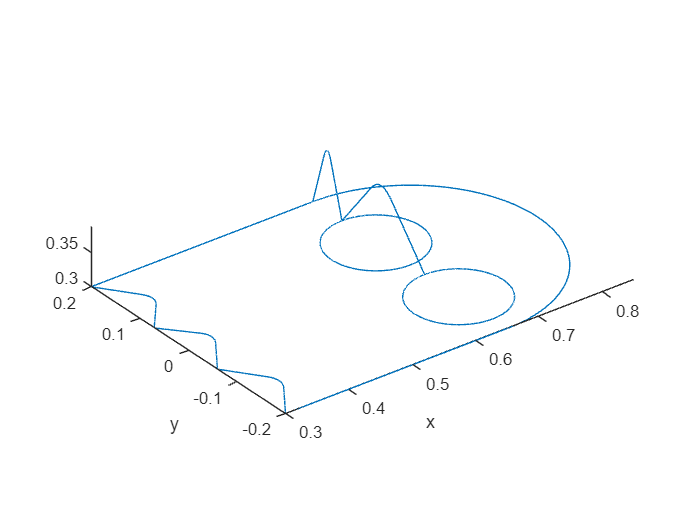

%% Plan the trajectory along a path characterized by at least 11 points within the workspace, in which there are at least one straight
%  portion and one circular portion and also the passage for at least 4 via points.

testa_sx            = [0.65 0.2   0.3]; % x,y,z
angolo_basso_sx     = [0.3  0.2   0.3];
fronte_onda_1       = [0.35 0.13  0.3];
base_onda_12        = [0.3  0.07  0.3];
fronte_onda_2       = [0.35 0.01  0.3];
base_onda_23        = [0.3  -0.06 0.3];
fronte_onda_3       = [0.35 -0.13 0.3];
angolo_basso_dx     = [0.3  -0.2  0.3];
testa_dx            = [0.65 -0.2  0.3];
centro_circ         = [0.65 0     0.3];
solleva_penna_1     = [0.65 0.17  0.4];
lato_occhio_sx      = [0.65 0.14  0.3];
centro_occhio_sx    = [0.65 0.07  0.3];
solleva_penna_2     = [0.65 0.06  0.4];
lato_occhio_dx      = [0.65 -0.03 0.3];
centro_occhio_dx    = [0.65 -0.10 0.3];

f_s = 1000;
tempo_traj = 20; % secondi

path_descr = struct("inizio", [testa_sx; angolo_basso_sx; fronte_onda_1; base_onda_12; fronte_onda_2; base_onda_23; fronte_onda_3; angolo_basso_dx;], ...
                "fine", [angolo_basso_sx; fronte_onda_1; base_onda_12; fronte_onda_2; base_onda_23; fronte_onda_3; angolo_basso_dx; testa_dx; ]);

[s_1,s_1_dot,s_1_dotdot] = trap_profile(0, 1,   f_s, testa_sx, angolo_basso_sx, tempo_traj, "rect");
[s_2,s_2_dot,s_2_dotdot] = trap_profile(1, 1.5, f_s, angolo_basso_sx, fronte_onda_1, tempo_traj, "via_point_inizio");
[s_3,s_3_dot,s_3_dotdot] = trap_profile(1.5, 2, f_s, fronte_onda_1, base_onda_12,tempo_traj, "via_point_fine");
[s_4,s_4_dot,s_4_dotdot] = trap_profile(2, 2.5, f_s, base_onda_12, fronte_onda_2,tempo_traj, "via_point_inizio");
[s_5,s_5_dot,s_5_dotdot] = trap_profile(2.5 ,3, f_s, fronte_onda_2, base_onda_23,tempo_traj, "via_point_fine");
[s_6,s_6_dot,s_6_dotdot] = trap_profile(3, 3.5, f_s, base_onda_23, fronte_onda_3,tempo_traj, "via_point_inizio");
[s_7,s_7_dot,s_7_dotdot] = trap_profile(3.5, 4, f_s, fronte_onda_3, angolo_basso_dx,tempo_traj, "via_point_fine");
[s_8,s_8_dot,s_8_dotdot] = trap_profile(4 ,5 ,  f_s, angolo_basso_dx, testa_dx, tempo_traj, "rect");
[s_9,s_9_dot,s_9_dotdot] = trap_profile(5, 8, f_s , 0, pi, tempo_traj, "circular");
[s_10,s_10_dot,s_10_dotdot] = trap_profile(8, 8.5, f_s, testa_sx, solleva_penna_1, tempo_traj, "via_point_inizio");
[s_11,s_11_dot,s_11_dotdot] = trap_profile(8.5, 9, f_s, solleva_penna_1, lato_occhio_sx,  tempo_traj, "via_point_fine");
[s_12,s_12_dot,s_12_dotdot] = trap_profile(9, 14, f_s, 0, 2*pi, tempo_traj, "circular");
[s_13,s_13_dot,s_13_dotdot] = trap_profile(14, 14.5, f_s, lato_occhio_sx, solleva_penna_2, tempo_traj, "via_point_inizio");
[s_14,s_14_dot,s_14_dotdot] = trap_profile(14.5, 15, f_s, solleva_penna_2,lato_occhio_dx, tempo_traj, "via_point_fine");
[s_15,s_15_dot,s_15_dotdot] = trap_profile(15, 20, f_s, 0, 2*pi, tempo_traj, "circular");

S = [s_1; s_2; s_3; s_4; s_5; s_6; s_7; s_8; s_9];
S_dot = [s_1_dot; s_2_dot; s_3_dot; s_4_dot; s_5_dot; s_6_dot; s_7_dot; s_8_dot; s_9_dot];
S_dotdot = [s_1_dotdot;s_2_dotdot;s_3_dotdot;s_4_dotdot;s_5_dotdot;s_6_dotdot;s_7_dotdot;s_8_dotdot; s_9_dotdot];

P = testa_sx;
P_dot = [0 0 0];
P_dotdot= [0 0 0];

for k = 1:size(path_descr.inizio, 1)
    [P, P_dot, P_dotdot] = lin_traj(P, P_dot, P_dotdot, S(k,:), S_dot(k,:), S_dotdot(k,:), path_descr.inizio(k,:), path_descr.fine(k,:));
end

rho_semicir = norm(testa_dx - centro_circ);
R = [0  1 0
     -1 0 0
     0  0 1];
s_9_plus = [zeros(3,5*f_s) ones(3,(tempo_traj-5)*f_s)];
P_9 = s_9_plus.*((centro_circ-testa_dx)' + R*[rho_semicir*cos(s_9)' rho_semicir*sin(s_9)' zeros(f_s*tempo_traj,1)]');
P = P + P_9';
P_dot = P_dot + (R*[-rho_semicir*s_9_dot.*sin(s_9); rho_semicir*s_9_dot.*cos(s_9); zeros(1,f_s*tempo_traj)])';
P_dotdot = P_dotdot + (R*[-((rho_semicir*s_9_dot).^2).*cos(s_9)/rho_semicir-rho_semicir*s_9_dotdot.*sin(s_9); -((rho_semicir*s_9_dot).^2).*sin(s_9)/rho_semicir+rho_semicir*s_9_dotdot.*cos(s_9); zeros(1,f_s*tempo_traj)])';

[P, P_dot, P_dotdot] = lin_traj(P, P_dot, P_dotdot, s_10, s_10_dot, s_10_dotdot, testa_sx, solleva_penna_1);
[P, P_dot, P_dotdot] = lin_traj(P, P_dot, P_dotdot, s_11, s_11_dot, s_11_dotdot, solleva_penna_1, lato_occhio_sx);

rho_cir = norm(centro_occhio_sx-lato_occhio_sx);
s_12_plus = [zeros(3,7*f_s) ones(3,(tempo_traj-7)*f_s)];
R_cir = [ 0 -1  0
         1  0  0
         0  0  1 ];
P_12 = s_12_plus.*((centro_occhio_sx-lato_occhio_sx)' + R_cir*[rho_cir*cos(s_12)' rho_cir*sin(s_12)' zeros(f_s*tempo_traj,1)]');
P = P + P_12';
P_dot = P_dot + (R_cir*[-rho_cir*s_12_dot.*sin(s_12); rho_cir*s_12_dot.*cos(s_12); zeros(1,f_s*tempo_traj)])';
P_dotdot = P_dotdot + (R_cir*[-((rho_cir*s_12_dot).^2).*cos(s_12)/rho_cir-rho_cir*s_12_dotdot.*sin(s_12); -((rho_cir*s_12_dot).^2).*sin(s_12)/rho_cir+rho_cir*s_12_dotdot.*cos(s_12); zeros(1,f_s*tempo_traj)])';

[P, P_dot, P_dotdot] = lin_traj(P, P_dot, P_dotdot, s_13, s_13_dot, s_13_dotdot, lato_occhio_sx, solleva_penna_2);
[P, P_dot, P_dotdot] = lin_traj(P, P_dot, P_dotdot, s_14, s_14_dot, s_14_dotdot, solleva_penna_2, lato_occhio_dx);

rho_cir = norm(centro_occhio_sx-lato_occhio_sx);
s_15_plus = [zeros(3,9*f_s) ones(3,(tempo_traj-9)*f_s)];
P_15 = s_12_plus.*((centro_occhio_dx-lato_occhio_dx)' + R_cir*[rho_cir*cos(s_15)' rho_cir*sin(s_15)' zeros(f_s*tempo_traj,1)]');
P = P + P_15';
P_dot = P_dot + (R_cir*[-rho_cir*s_15_dot.*sin(s_15); rho_cir*s_15_dot.*cos(s_15); zeros(1,f_s*tempo_traj)])';
P_dotdot = P_dotdot + (R_cir*[-((rho_cir*s_15_dot).^2).*cos(s_15)/rho_cir-s_15_dotdot.*sin(s_15); -((rho_cir*s_15_dot).^2).*sin(s_15)/rho_cir+rho_cir*s_15_dotdot.*cos(s_15); zeros(1,f_s*tempo_traj)])';


plot3(P(:,1),P(:,2),P(:,3))
xlabel("x")
ylabel("y")
axis equal

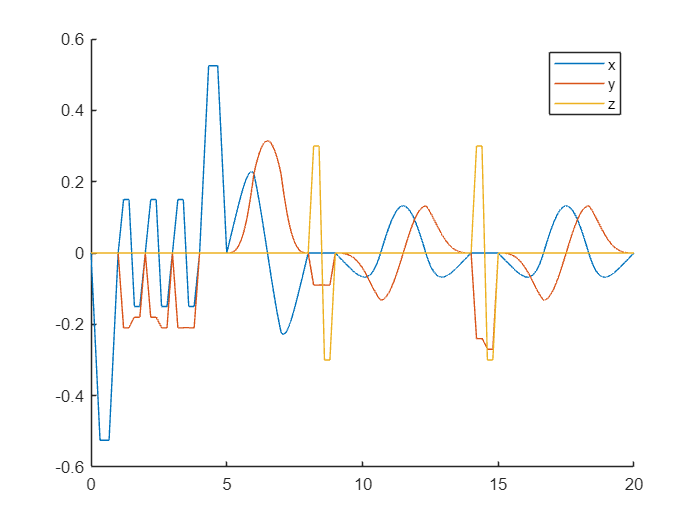

t = linspace(0, 20, size(P_dot, 1));
figure("Name", "P_dot")
hold on
for i = 1:size(P_dot, 2)
    plot(t, P_dot(:,i));
end
legend("x", "y", "z")

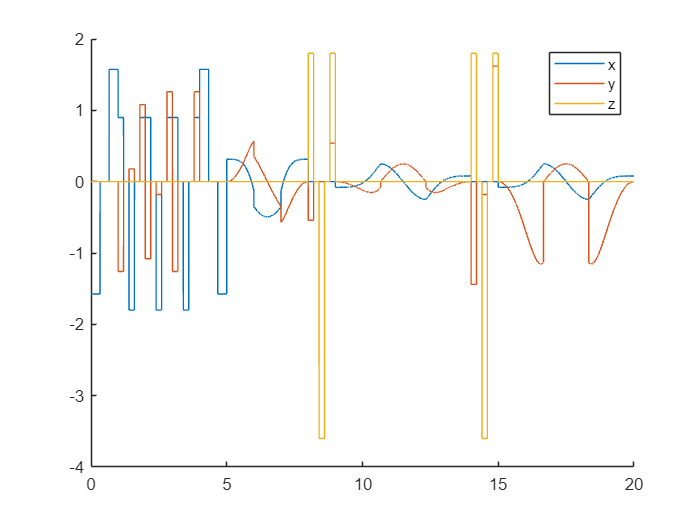

figure("Name", "P_dotdot")
hold on
for i = 1:size(P_dotdot, 2)
    plot(t, P_dotdot(:,i));
end
legend("x", "y", "z");
hold off

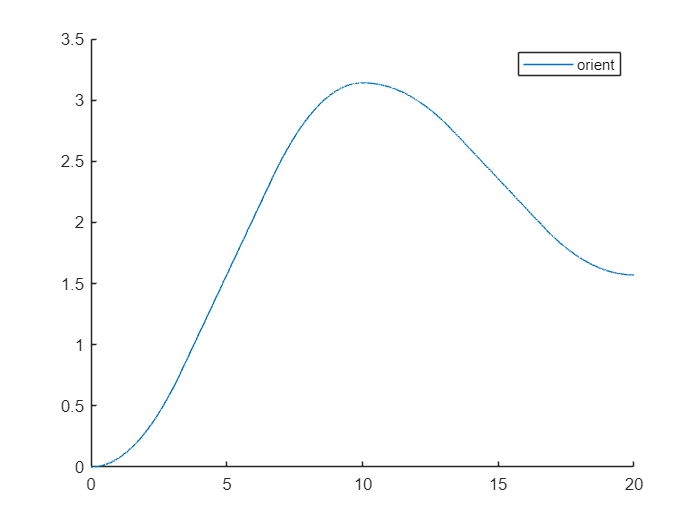

%%ORIENTATION%%

rot_0 = 0;
rot_1 = pi;
rot_2 = pi/2;

[s_rot_1, s_rot_1_dot, s_rot_1_dotdot] = trap_profile(0, 10, f_s, rot_0, rot_1, tempo_traj, "rect");
[s_rot_2, s_rot_2_dot, s_rot_2_dotdot] = trap_profile(10, 20, f_s, rot_1, rot_2, tempo_traj, "rect");

P_o = rot_0 + s_rot_1/(norm(rot_1-rot_0))*(rot_1-rot_0) + s_rot_2/(norm(rot_2-rot_1))*(rot_2-rot_1);
P_o_dot = s_rot_1_dot/(norm(rot_1-rot_0))*(rot_1-rot_0) + s_rot_2_dot/(norm(rot_2-rot_1))*(rot_2-rot_1);
P_o_dotdot = s_rot_1_dotdot/(norm(rot_1-rot_0))*(rot_1-rot_0) + s_rot_2_dotdot/(norm(rot_2-rot_1))*(rot_2-rot_1);


t_o = linspace(0, 20, size(P_o,2));
figure("Name", "P_o")
hold on
plot(t_o, P_o);
legend ("orient")

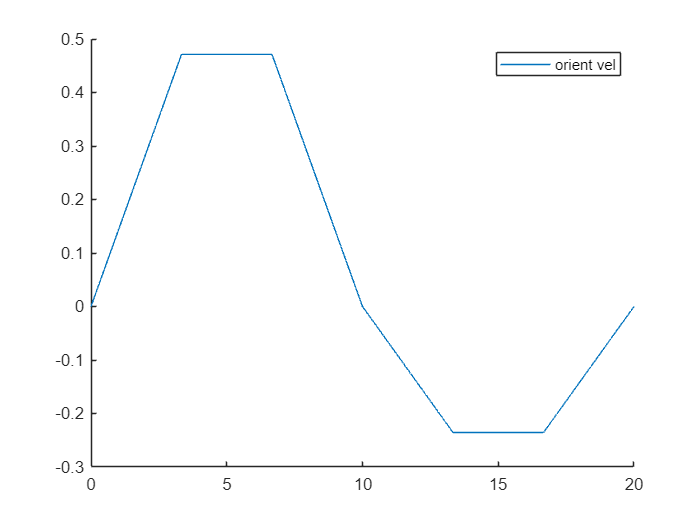

figure("Name", "P_o_dot")
hold on
plot(t_o, P_o_dot);
legend ("orient vel")

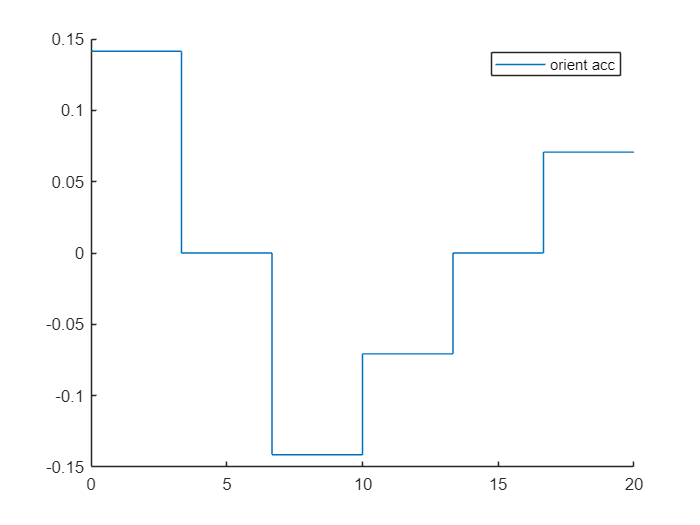

figure("Name", "P_o_dotdot")
hold on
plot(t_o, P_o_dotdot);
legend ("orient acc")
hold off

## CLIK Algorithms

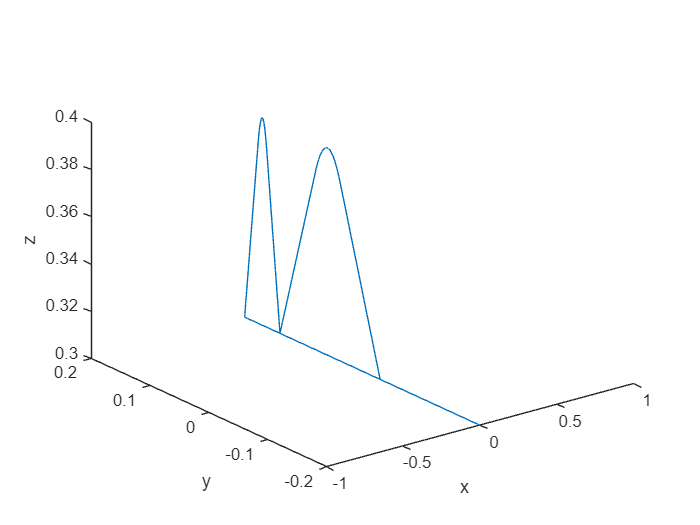

%% Implement the CLIK algorithms in MATLAB with both Jacobian inverse and transpose along the trajectory. Adopt Euler numerical
%  integration rule with sampling period of 1 ms.
Tempo = 0:1/f_s:tempo_traj-1/f_s;
P_tot = [P, P_o'];
P_dot_tot = [P_dot, P_o_dot'];
P_dotdot_tot = [P_dotdot, P_o_dotdot'];
x_d = timeseries(P_tot, Tempo);
x_d_dot = timeseries(P_dot_tot, Tempo);
x_d_dotdot = timeseries(P_dotdot_tot, Tempo);
config_p_init = [1.1214 -1.6459  0.2 -0.5245];

%% Assuming to relax an operational space component, implement the CLIK algorithm in MATLAB with Jacobian pseudo-inverse
%  along the trajectory when optimizing a dexterity constraint.
w = sqrt(det(J_min*J_min'));
x_d_relax = timeseries(P_tot(:,2:4), Tempo);
plot3(zeros(size(P, 1), 1),P(:,2),P(:,3))
xlabel("x")
ylabel("y")
zlabel("z")

x_d_dot_relax = timeseries(P_dot_tot(:,2:4), Tempo);
q_0_dot = simplify([diff(w, theta_1) diff(w, theta_2) diff(w, d_3) diff(w, theta_4)])

$$q\_0\_dot = \left(\begin{array}{cccc} 0 & \frac{\sqrt{2}\,\sin\left(2\,\theta_{2}\right)}{8\,\sqrt{1-\cos\left(2\,\theta_{2}\right)}} & 0 & 0 \end{array}\right)$$

## Inversione cinematica con pseudoinversa

%% Consider a concentrated end-effector payload of about 5 kg. Then, design: 1) a robust control; 2) an adaptive control; 3) an
%  operational space inverse dynamics control with the adoption of an integral action to recover the steady-state error due to the
%  uncompensated load. Simulate in MATLAB the motion of the controlled manipulator under the assumption that the desired joint
%  trajectories for the first two controllers are generated with a 2nd-order CLIK algorithm. Implement discrete-time controllers with
%  a sampling period of 1 ms

dh_din =[a_1/2   0	    d_0 	    theta_1
         a_2/2   pi     0           theta_2
         0       0      l_1+d_3	    0
         0   	 0      l_2		    theta_4-pi/2];

A_1_prime = transf_mat(dh_din(1,:));
A_2_prime = transf_mat(dh_din(2,:));
A_3_prime = transf_mat(dh_din(3,:));

p_0 = [0 0 1]';
p_l1_tilde =  A_1_prime*p_0_tilde;
p_l1 = p_l1_tilde(1:3,:);
p_l2_tilde =  A_1*A_2_prime*p_0_tilde;
p_l2 = p_l2_tilde(1:3,:);
p_l3_tilde =  A_1*A_2*A_3_prime*p_0_tilde;
p_l3 = p_l3_tilde(1:3,:);

J_l1_P1 = cross(z_0,p_l1-p_0);
J_l2_P1 = cross(z_0,p_l2-p_0);
J_l2_P2 = cross(z_1,p_l2-p_1);
J_l3_P1 = cross(z_0,p_l3-p_0);
J_l3_P2 = cross(z_1,p_l3-p_1);
J_l3_P3 = z_2;

J_l1_P = [J_l1_P1 zeros(3,1) zeros(3,1) zeros(3,1)];
J_l2_P = [J_l2_P1 J_l2_P2    zeros(3,1) zeros(3,1)];
J_l3_P = [J_l3_P1 J_l3_P2    J_l3_P3    zeros(3,1)];

J_l1_O1 = z_0;
J_l2_O1 = z_0;
J_l2_O2 = z_1;
J_l3_O1 = z_0;
J_l3_O2 = z_1;
J_l3_O3 = zeros(3,1);
J_l3_O4 = z_3;

J_l1_O = [J_l1_O1 zeros(3,1) zeros(3,1) zeros(3,1)];
J_l2_O = [J_l2_O1 J_l2_O2    zeros(3,1) zeros(3,1)];
J_l3_O = [J_l3_O1 J_l3_O2    J_l3_O3    J_l3_O4   ];

R_l1 = A_1(1:3,1:3);
R_l2 = A_1(1:3,1:3)*A_2(1:3,1:3);
R_l3 = A_1(1:3,1:3)*A_2(1:3,1:3)*A_4(1:3,1:3);

IL_1 = zeros(3,3);
IL_1(9) = I_l1;
IL_2 = zeros(3,3);
IL_2(9) = I_l2;
IL_3 = zeros(3,3);
IL_3(9) = I_l4;

p_m1 = p_0;
p_m2 = p_1;
p_m3 = p_2;
p_m4 = p_l3;

J_m2_P1 = cross(z_0,p_m2-p_0);
J_m3_P1 = cross(z_0,p_m3-p_0);
J_m3_P2 = cross(z_1,p_m3-p_1);
J_m4_P1 = cross(z_0,p_m4-p_0);
J_m4_P2 = cross(z_1,p_m3-p_1);
J_m4_P3 = z_2;

J_m1_P = [zeros(3,1) zeros(3,1) zeros(3,1) zeros(3,1)];
J_m2_P = [J_m2_P1    zeros(3,1) zeros(3,1) zeros(3,1)];
J_m3_P = [J_m3_P1    J_m3_P2    zeros(3,1) zeros(3,1)];
J_m4_P = [J_m4_P1    J_m4_P2    J_m4_P3    zeros(3,1)];

J_m1_O1 = k_r1*z_0;
J_m2_O1 = J_l2_O1;
J_m2_O2 = k_r2*z_1;
J_m3_O1 = J_l3_O1;
J_m3_O2 = J_l3_O2;
J_m3_O3 = k_r3*z_2;
J_m4_O1 = J_l3_O1;
J_m4_O2 = J_l3_O2;
J_m4_O3 = J_l3_O3;
J_m4_O4 = k_r4*z_2;

J_m1_O = [J_m1_O1 zeros(3,1) zeros(3,1) zeros(3,1)];
J_m2_O = [J_m2_O1 J_m2_O2    zeros(3,1) zeros(3,1)];
J_m3_O = [J_m3_O1 J_m3_O2    J_m3_O3    zeros(3,1)];
J_m4_O = [J_m4_O1 J_m4_O2    J_m4_O3    J_m4_O4   ];

R_m1 = eye(3);
R_m2 = R_l1;
R_m3 = R_l2;
R_m4 = R_l2;

IM_1 = zeros(3,3);
IM_1(9) = I_m1;
IM_2 = zeros(3,3);
IM_2(9) = I_m2;
IM_3 = zeros(3,3);
IM_3(9) = I_m3;
IM_4 = zeros(3,3);
IM_4(9) = I_m4;

B = m_l(1).*J_l1_P'*J_l1_P+m_l(2).*J_l2_P'*J_l2_P +m_l(3).*J_l3_P'*J_l3_P;
B = B + J_l1_O'*R_l1*IL_1*R_l1'*J_l1_O + J_l2_O'*R_l2*IL_2*R_l2'*J_l2_O + J_l3_O'*R_l3*IL_3*R_l3'*J_l3_O;
B = simplify(B + J_m1_O'*R_m1*IM_1*R_m1'*J_m1_O + J_m2_O'*R_m2*IM_2*R_m2'*J_m2_O + J_m3_O'*R_m3*IM_3*R_m3'*J_m3_O + J_m4_O'*R_m4*IM_4*R_m4'*J_m4_O)

$$B = \left(\begin{array}{cccc} 10\,\cos\left(\theta_{2}\right)+\frac{10763}{500} & 5\,\cos\left(\theta_{2}\right)+\frac{4383}{500} & -\frac{1}{4} & -\frac{51}{50}\\ 5\,\cos\left(\theta_{2}\right)+\frac{4383}{500} & \frac{4383}{500} & -\frac{1}{4} & -\frac{51}{50}\\ -\frac{1}{4} & -\frac{1}{4} & \frac{45}{2} & 0\\ -\frac{51}{50} & -\frac{51}{50} & 0 & \frac{7}{5} \end{array}\right)$$

B_p = m_l(1).*J_l1_P'*J_l1_P+m_l(2).*J_l2_P'*J_l2_P +(m_l(3)+5).*J_l3_P'*J_l3_P;
B_p = B_p + J_l1_O'*R_l1*IL_1*R_l1'*J_l1_O + J_l2_O'*R_l2*IL_2*R_l2'*J_l2_O + J_l3_O'*R_l3*IL_3*R_l3'*J_l3_O;
B_p = simplify(B_p + J_m1_O'*R_m1*IM_1*R_m1'*J_m1_O + J_m2_O'*R_m2*IM_2*R_m2'*J_m2_O + J_m3_O'*R_m3*IM_3*R_m3'*J_m3_O + J_m4_O'*R_m4*IM_4*R_m4'*J_m4_O)

$$B\_p = \begin{array}{l} \left(\begin{array}{cccc} \frac{25\,\cos\left(\theta_{2}\right)}{2}+\frac{12013}{500} & \sigma_{1} & -\frac{1}{4} & -\frac{51}{50}\\ \sigma_{1} & \frac{1252}{125} & -\frac{1}{4} & -\frac{51}{50}\\ -\frac{1}{4} & -\frac{1}{4} & \frac{55}{2} & 0\\ -\frac{51}{50} & -\frac{51}{50} & 0 & \frac{7}{5} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{25\,\cos\left(\theta_{2}\right)}{4}+\frac{1252}{125} \end{array}$$

for i=1:4
    for j=1:4
        c_ijk = [];
        for k=1:4
           c_ijk = [c_ijk; 1/2*(diff(B(i,j),q(k)) + diff(B(i,k),q(j)) - diff(B(j,k),q(i)))];
        end
        C(i,j) = c_ijk(1)*theta_dot_1 + c_ijk(2)*theta_dot_2 + c_ijk(3)*d_dot_3 + c_ijk(4)*theta_dot_4;
    end
end
C

$$C = \left(\begin{array}{cccc} -5\,{\dot{\theta }}_{2}\,\sin\left(\theta_{2}\right) & -5\,{\dot{\theta }}_{1}\,\sin\left(\theta_{2}\right)-5\,{\dot{\theta }}_{2}\,\sin\left(\theta_{2}\right) & 0 & 0\\ 5\,{\dot{\theta }}_{1}\,\sin\left(\theta_{2}\right) & 0 & 0 & 0\\ 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 \end{array}\right)$$

for i=1:4
    for j=1:4
        c_ijk = [];
        for k=1:4
           c_ijk = [c_ijk; 1/2*(diff(B_p(i,j),q(k)) + diff(B_p(i,k),q(j)) - diff(B_p(j,k),q(i)))];
        end
        C_p(i,j) = c_ijk(1)*theta_dot_1 + c_ijk(2)*theta_dot_2 + c_ijk(3)*d_dot_3 + c_ijk(4)*theta_dot_4;
    end
end
C_p

$$C\_p = \left(\begin{array}{cccc} -\frac{25\,{\dot{\theta }}_{2}\,\sin\left(\theta_{2}\right)}{4} & -\frac{25\,{\dot{\theta }}_{1}\,\sin\left(\theta_{2}\right)}{4}-\frac{25\,{\dot{\theta }}_{2}\,\sin\left(\theta_{2}\right)}{4} & 0 & 0\\ \frac{25\,{\dot{\theta }}_{1}\,\sin\left(\theta_{2}\right)}{4} & 0 & 0 & 0\\ 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 \end{array}\right)$$

## ROBUST CONTROL

Kp_r = diag([1000 1000 2000 1000]);
Kd_r = diag([500 500 1000 500]);
D= [zeros(4); eye(4)]; 
H = [zeros(4,4), eye(4); zeros(4,8)];
K_rob=[Kp_r Kd_r];
Htilde = H-D*K_rob;
P_lyap = diag([1 1 1 1 1 1 1 1]);
Q = lyap(Htilde,P_lyap);

## ADAPTIVE CONTROL

Lambda = diag([10 10 50 1]);
pi_0 = [m_l1 m_l2 m_l3 I_l1 I_l2 I_l4 I_m1 I_m2 I_m3 I_m4 F_m1 F_m2 F_m3 F_m4]';
Kd_ad = diag([500 500 10000 500]);

## Operational Space control

% Kp_op = diag([50 50 250 50]); 
% Ki_op = diag([5 20 60 10]); 
% Kd_op = diag([60 15 30 10]); 

Kp_op = diag([5000 10000 10000 5000]); 
Ki_op = diag([2000 4000 2000 2000]); 
Kd_op = diag([100 100 100 100]);
